# Design of Shell and Tube Heat Exchanger

#### *E351 - Water Cooled Ammonia Condenser*

Group 12: Aswin Raghunathan (5128188) & Shyam Sundar Hemamalini (5071984)

## 1.1. Estimating heat flux from given specification

We are given the following specifications.

m_amm = 14; % kg/s
h_amm_l = 399.11*1000; % J/kg
h_amm_g = 1617.0*1000; % J/kg

Now, the duty can be determined as:

Q_dot = m_amm*(h_amm_g - h_amm_l) % W

Q_dot = 17050460

## 1.2. Performing energy balance to determine outlet temperature

The following specifications are also provided.

m_water = 680; % kg/s
T_in_water = 5 + 273.15; % K
Cp_water = 4205.3; % J/kgK

A simple substitution in the energy balance will give us the outlet temperature of water as:

T_out_water = T_in_water + Q_dot/(m_water*Cp_water) % K

T_out_water = 284.1125

## 2. Physical Properties

The physical properties of both water and ammonia are evaluated at the mean temperature as:

rho_amm_l = 621.79; % kg/m^3
rho_water_l = 999.8; % kg/m^3
rho_amm_g = 5.1983; % kg/m^3
visc_amm_l = 1.4992e-4; % Pa s
visc_amm_g = 9.4259e-6; % Pa s
visc_water_l = 1.3857e-3; % Pa s
k_amm_l = 0.5232; % W/mK
k_water_l = 0.57618; % W/mK

## 3. Initial Overall Heat Transfer Coefficient

The initial value has been assumed from the chart given in Sinnott and Towler as:

U_0_init = 900 % W/m^2K

U_0_init = 900

## 4.1. Shell and tube passes

The number of tube passes is initially assumed to be 6.

N_p = 6;

## 4.2. Determination of LMTD

T_in_amm = 12 + 273.15; % K
T_out_amm = 12 + 273.15; % K
T_mean_shell = (T_in_amm + T_out_amm)/2;
T_mean_tube = (T_in_water + T_out_water)/2;

Now, we have the formula for logarithmic mean temperature difference as:

T_lmtd = ((T_in_amm-T_out_water)-(T_out_amm-T_in_water))/...
    log((T_in_amm - T_out_water)/(T_out_amm - T_in_water)) % K

T_lmtd = 3.1232

## 5. Determination of Heat Transfer Area

From the assumed value of heat transfer coefficient, the heat transfer area can be approximated as:

A0 = Q_dot / (U_0_init*T_lmtd) % m^2

A0 = 6.0659e+03

## 6. Determination of Design Parameters

The following design assumptions are made:

d_out = 0.019; % m
t_wall = 0.0017; % m
L_tube = 7.32; % m

Depending on the above assumptions, we determine the following design values.

pitch_tube = 1.25*d_out % pitch in m

pitch_tube = 0.0238

d_in = d_out - 2*t_wall % inner diameter in m

d_in = 0.0156

## 7.1. Determination of Number of Tubes

For cylindrical tubes of the above design values, the heat transfer area translates as:

N_tubes = A0 / (pi*d_out*L_tube) % number of tubes

N_tubes = 1.3883e+04

N_hex = 11 % number of heat exchangers

N_hex = 11

N_t_hex = round(N_tubes/N_hex) % number of tubes per heat exchanger

N_t_hex = 1262

## 7.2. Determination of Tube Velocity

Now, we can determine an estimate of the velocity of water in the tubes as:

velocity_water = 4*m_water*N_p/...
    (rho_water_l*pi*(d_in^2)*N_tubes) % m/s

velocity_water = 1.5379

Also, the Reynolds number is given by:

reynolds = rho_water_l*velocity_water*d_in/visc_water_l

reynolds = 1.7310e+04

## 8. Calculation of Shell Diameter

For 6 tube side passes, we have the values of K1 and n1 and hence, the design values of the shell can be determined as:

K1 = 0.0402; % for 6 tube passes
n1 = 2.617;
d_bundle = d_out*(N_t_hex/K1)^(1/n1) % m

d_bundle = 0.9933

tolerance = (10 + (20-10)*(d_bundle - 0.2)/(1.2 - 0.2))/1000 % m

tolerance = 0.0179

d_shell_i = d_bundle + tolerance % m

d_shell_i = 1.0112

N_center = round(d_bundle / pitch_tube) % number of tubes in center row

N_center = 42

## 9.1. Estimation of Tube Side Heat Transfer Coefficient

The mean bulk temperature of water inside the tubes is given by:

T_water_mean = (T_in_water + T_out_water)/2; % K
T_wm_C = T_water_mean - 273.15; % °C

The above can be substituted in the correlation by Eagle and Ferguson for water as:

h_i = (4200*(1.35+0.02*T_wm_C)*(velocity_water^0.8))/((d_in*1000)^0.2) % W/m^2K

h_i = 5.1646e+03

## 9.2. Estimation of Tube Side Heat Transfer Coefficient - Kern's Method

An alternative to the above method is the Kern's method. However, here, we need the correction for viscosity. We first determine the thermophysical properties for water at the mean bulk temperature.

prandtl = Cp_water*visc_water_l/k_water_l;
E = 0.0225*exp(-0.0225*(log(prandtl))^2);
stanton = E * (reynolds^-0.205) * (prandtl^-0.505);
jh = stanton*prandtl^0.67;

Now, we implement the viscosity correction and determine the viscosity of water near the wall.

T_wall_tube = T_mean_tube + U_0_init*(T_mean_shell - T_mean_tube)/h_i % K

T_wall_tube = 281.8316

visc_water_w = 1.3571e-3; % Pa s

This is then substituted in the correlation to determine the heat transfer coefficient.

h_i_kern1 = k_water_l*jh*reynolds*(prandtl^0.33)*((visc_water_l/visc_water_w)^0.14)/d_in % W/m^2K

h_i_kern1 = 5.4380e+03

Since the above value is higher than the previously computed value, this is ignored.

## 10. Shell Side Heat Transfer Coefficient

The initial guess for shell side heat transfer coefficient is:

U_amm_init = 7275; % W/m^2K

The viscosity correction factor is then determined from the wall temperature.

T_wall = T_mean_shell - (T_mean_shell - T_mean_tube)*U_0_init/U_amm_init % K

T_wall = 284.6528

T_amm_con = (T_mean_shell + T_wall)/2 % K

T_amm_con = 284.9014

visc_amm_c = 1.503e-4; % Pa s
rho_amm_c = 622.15; % kg/m^3
k_amm_c = 0.52394; % W/mK
rho_amm_v = 5.1983; % kg/m^3

The tube loading is determined as below. 

gamma = m_amm/(L_tube*N_t_hex) % kg/ms

gamma = 0.0015

N_r = 2*N_center/3

N_r = 28

As we employ a shell-side condensing horizontal axis heat exchanger, we use the following correlation to determined the heat transfer coefficient.

h_c_shell = 0.95 * k_amm_c *((rho_amm_c*(rho_amm_c-rho_amm_v)*9.81)/...
    (visc_amm_c*gamma))^(1/3) * (N_r^(-1/6)) % W/m^2K

h_c_shell = 7.2763e+03

## 11. Overall Heat Transfer Coefficient

Sea water, typically used in OTEC, is heavily fouling while ammonia is less fouling. Hence, the following values are assumed as the fouling factors. Also, as we consider the tube material to be low carbon steel, we have the following value for thermal conductivity.

fouling_water = 1000; % W/m^2K
fouling_ammonia = 5000; % W/m^2K
k_steel = 54; % W/mK

Computing the overall heat transfer coefficient is done as below:

val = (h_c_shell^-1) + (fouling_ammonia^-1) + d_out * log(d_out/d_in) / (2*k_steel) +...
    d_out/(d_in*fouling_water) + d_out/(d_in*h_i);
U1 = val^-1 % W/m^2K

U1 = 547.6765

## Calculating Error

Error = (U_0_init - U1)/U_0_init*100 % in percentage

Error = 39.1471

The error, which is about 39%, exceeds the permissible limits. Hence, we take a new value for the overall heat transfer coefficient as the new guess and repeat.

## 3*. Initial Overall Heat Transfer Coefficient

U_0_init = 555; % W/m^2K

## 5*. Determination of Heat Transfer Area

A0 = Q_dot / (U_0_init*T_lmtd) % m^2

A0 = 9.8366e+03

## 6*. Determination of Design Parameters

d_out = 0.019; % m
t_wall = 0.0017; % m
L_tube = 7.32; % m
N_p = 8; % increasing the passes to increase the velocity in tubes
pitch_tube = 1.25*d_out % m

pitch_tube = 0.0238

d_in = d_out - 2*t_wall % m

d_in = 0.0156

## 7.1*. Determination of Number of Tubes

N_tubes = A0 / (pi*d_out*L_tube) % number of tubes

N_tubes = 2.2513e+04

N_hex = 21

N_hex = 21

N_t_hex = round(N_tubes/N_hex) 

N_t_hex = 1072

## 7.2*. Determination of Tube Velocity

velocity_water = 4*m_water*N_p/(rho_water_l*pi*(d_in^2)*N_tubes) % m/s

velocity_water = 1.2645

reynolds = rho_water_l*velocity_water*d_in/visc_water_l

reynolds = 1.4233e+04

Both the velocity and the Reynolds number are within the permissible limits after changes to design.

## 8*. Calculation of Shell Diameter

K1 = 0.0331; % for 8 tube passes
n1 = 2.643;
d_bundle = d_out*(N_t_hex/K1)^(1/n1) % m

d_bundle = 0.9667

tolerance = (10 + (20-10)*(d_bundle - 0.2)/(1.2 - 0.2))/1000 % m

tolerance = 0.0177

d_shell_i = d_bundle + tolerance % m

d_shell_i = 0.9844

N_center = round(d_bundle / pitch_tube) % tubes in center row

N_center = 41

## 9.1*. Estimation of Tube Side Heat Transfer Coefficient

T_water_mean = (T_in_water + T_out_water)/2; % K
T_wm_C = T_water_mean - 273.15; % °C
h_i = (4200*(1.35+0.02*T_wm_C)*(velocity_water^0.8))/((d_in*1000)^0.2) % W/m^2K

h_i = 4.4160e+03

The changes to the tube side heat transfer coefficient is not pronounced.

## 9.2*. Estimation of Tube Side Heat Transfer Coefficient - Kern's Method

prandtl = Cp_water*visc_water_l/k_water_l;
E = 0.0225*exp(-0.0225*(log(prandtl))^2);
stanton = E * (reynolds^-0.205) * (prandtl^-0.505);
jh = stanton*prandtl^0.67;
T_wall_tube = T_mean_tube + U_0_init*(T_mean_shell - T_mean_tube)/h_i % K

T_wall_tube = 281.6363

visc_water_w = 1.365e-3; % Pa s
h_i_kern = k_water_l*jh*reynolds*(prandtl^0.33)*((visc_water_l/visc_water_w)^0.14)/d_in % W/m^2K

h_i_kern = 4.6505e+03

## 10*. Shell Side Heat Transfer Coefficient

U_amm_init = 7275; % W/m^2K
T_wall = T_mean_shell - (T_mean_shell - T_mean_tube)*U_0_init/U_amm_init % K

T_wall = 284.8434

T_amm_con = (T_mean_shell + T_wall)/2 % K

T_amm_con = 284.9967

visc_amm_c = 1.503e-4; % Pa s
rho_amm_c = 622.15; % kg/m^3
k_amm_c = 0.52394; % W/mK
rho_amm_v = 5.1983; % kg/m^3
gamma = m_amm/(L_tube*N_t_hex) % kg/ms

gamma = 0.0018

N_r = 2*N_center/3

N_r = 27.3333

h_c_shell = 0.95 * k_amm_c *((rho_amm_c*(rho_amm_c-rho_amm_v)*9.81)/...
    (visc_amm_c*gamma))^(1/3) * (N_r^(-1/6)) % W/m^2K

h_c_shell = 6.9189e+03

Whereas, the heat transfer coefficient increases slightly in the shell side.

## 11*. Overall Heat Transfer Coefficient

fouling_water = 1000; % W/m^2K
fouling_ammonia = 5000; % W/m^2K
k_steel = 57; % W/mK
val = (h_c_shell^-1) + (fouling_ammonia^-1) + d_out * log(d_out/d_in) / (2*k_steel) +...
    d_out/(d_in*fouling_water) + d_out/(d_in*h_i);
U1 = val^-1 % W/m^2K

U1 = 534.4312

The newly computed value varies slightly from the assumed value.

## Calculating Error

Error = (U_0_init - U1)/U_0_init*100 % in percentage

Error = 3.7061

The error between the values is about 3.7% which is well within the permissible limits. Hence, we can proceed to determine the pressure drop in the tube and shell side.

## 12. Tube Side Pressure Drop

Estimating the tube side pressure drop is done taking in account the viscosity correction factor as below:

jf = 4.5e-3; % friction factor
m = 0.14; % turbulent flow
P_tube = N_p * (8*jf*L_tube/d_in*(visc_water_l/visc_water_w)^(-m) + 2.5) ...
    * rho_water_l * velocity_water^2 /2 % Pa

P_tube = 1.2378e+05

The obtained value for the pressure drop, approximately 124 kPa, is higher than the permissible limit of 70 kPa. Hence, we change the design values to incorporate a lower pressure drop.

## 3**. Initial Overall Heat Transfer Coefficient

We use a better guess for the overall heat transfer coefficient as:

U_0_init = 527; % W/m^2K

## 5**. Determination of Heat Transfer Area

A0 = Q_dot / (U_0_init*T_lmtd) % m^2

A0 = 1.0359e+04

## 6**. Determination of Design Parameters

We reduce the length of tubing, thereby reducing the pressure drop.

d_out = 0.019; % m
t_wall = 0.0017; % m
L_tube = 6.1; % m
N_p = 8;
pitch_tube = 1.25*d_out % pitch in m

pitch_tube = 0.0238

d_in = d_out - 2*t_wall % inner diameter in m

d_in = 0.0156

## 7.1**. Determination of Number of Tubes

However, we see an increase in the number of tubes and hence, the number of heat exchangers.

N_tubes = A0 / (pi*d_out*L_tube) % number of tubes

N_tubes = 2.8451e+04

N_t_hex = 1166;
N_hex = ceil(N_tubes/N_t_hex)

N_hex = 25

## 7.2**. Determination of Tube Velocity

velocity_water = 4*m_water*N_p/...
    (rho_water_l*pi*(d_in^2)*N_tubes) % m/s

velocity_water = 1.0006

The determined value of velocity is very close to the recommended minimum bound for liquid flow in tubes.

reynolds = rho_water_l*velocity_water*d_in/visc_water_l

reynolds = 1.1262e+04

## 8**. Calculation of Shell Diameter

K1 = 0.0331; % for 8 tube passes
n1 = 2.643;
d_bundle = d_out*(N_t_hex/K1)^(1/n1) % m

d_bundle = 0.9979

The assumed values of design align almost perfectly with the industrial standards for shell sizes.

tolerance = (10 + (20-10)*(d_bundle - 0.2)/(1.2 - 0.2))/1000 % m

tolerance = 0.0180

d_shell_i = d_bundle + tolerance % m

d_shell_i = 1.0159

N_center = floor(d_bundle / pitch_tube)

N_center = 42

## 9.1**. Estimation of Tube Side Heat Transfer Coefficient

T_water_mean = (T_in_water + T_out_water)/2; % K
T_wm_C = T_water_mean - 273.15; % °C

The corrected value for the tube side heat transfer coefficient is:

h_i = (4200*(1.35+0.02*T_wm_C)*(velocity_water^0.8))/((d_in*1000)^0.2) % W/m^2K

h_i = 3.6618e+03

## 9.2**. Estimation of Tube Side Heat Transfer Coefficient - Kern's Method

prandtl = Cp_water*visc_water_l/k_water_l;
E = 0.0225*exp(-0.0225*(log(prandtl))^2);
stanton = E * (reynolds^-0.205) * (prandtl^-0.505);
jh = stanton*prandtl^0.67;

Taking into account the redefined value for wall film viscosity as:

T_wall_tube = T_mean_tube + U_0_init*(T_mean_shell - T_mean_tube)/h_i % K

T_wall_tube = 281.7096

visc_water_w = 1.362e-3; % Pa s

Hence, we obtain a better estimate for the tube side heat transfer coefficient.

h_i_kern = k_water_l*jh*reynolds*(prandtl^0.33)*((visc_water_l/visc_water_w)^0.14)/d_in % W/m^2K

h_i_kern = 3.8620e+03

## 10**. Shell Side Heat Transfer Coefficient

baffle_s = d_shell_i; % m
U_amm_init = 7275; % W/m^2K

For the redefined design parameters and hence, the recalculated temperatures, we define the shell side fluid mean properties.

T_wall = T_mean_shell - (T_mean_shell - T_mean_tube)*U_0_init/U_amm_init % K

T_wall = 284.8589

T_amm_con = (T_mean_shell + T_wall)/2 % K

T_amm_con = 285.0044

visc_amm_c = 1.5014e-4; % Pa s
rho_amm_c = 622.00; % kg/m^3
k_amm_c = 0.52363; % W/mK
rho_amm_v = 5.1736; % kg/m^3
gamma = m_amm/(L_tube*N_t_hex) % kg/ms

gamma = 0.0020

N_r = 2*N_center/3

N_r = 28

Hence, we evaluate the shell side heat transfer coefficient as below.

h_c_shell = 0.95 * k_amm_c *((rho_amm_c*(rho_amm_c-rho_amm_v)*9.81)/...
    (visc_amm_c*gamma))^(1/3) * (N_r^(-1/6)) % W/m^2K

h_c_shell = 6.6665e+03

## 11**. Overall Heat Transfer Coefficient

fouling_water = 1000; % W/m^2K
fouling_ammonia = 5000; % W/m^2K
k_steel = 57; % W/mK

We substitute the recalculated values to determine the value for the overall heat transfer coefficient.

val = (h_c_shell^-1) + (fouling_ammonia^-1) + d_out * log(d_out/d_in) / (2*k_steel) +...
    d_out/(d_in*fouling_water) + d_out/(d_in*h_i);
U1 = val^-1 % W/m^2K

U1 = 517.2173

The obtained value is very close to the assumed value.

## Calculating Error

Error = (U_0_init - U1)/U_0_init*100 % in percentage

Error = 1.8563

The error between the assumed value and the guess is about 1.8% which is again well within the permissible limits.

## 12.1. Tube Side Pressure Drop

jf = 4.5e-3; % friction factor
m = 0.14; % turbulent flow

However, recalculating the tube side pressure drop gives us:

P_tube = N_p * (8*jf*L_tube/d_in*(visc_water_l/visc_water_w)^(-m) + 2.5) ...
    * rho_water_l * velocity_water^2 /2 % Pa

P_tube = 6.6235e+04

The obtained value for the tube side pressure drop is about 66.2 kPa which is acceptable. Hence, we can proceed to determine the shell side pressure drop.

## 12.2. Shell Side Pressure Drop - Kern

A few geometrical and flow properties of the shell side are calculated beforehand.

A_s = (pitch_tube - d_out)*d_shell_i*baffle_s/(pitch_tube); % m^2
mass_velocity_shell = m_amm/A_s; % kg/s
velocity_shell = mass_velocity_shell/rho_amm_l % m/s

velocity_shell = 0.1091

d_e = 1.27*(pitch_tube^2 - 0.785*(d_out^2))/d_out; % equivalent diameter in m
reynolds_shell = velocity_shell*d_e*rho_amm_l/visc_amm_l 

reynolds_shell = 8.4877e+03

Cp_amm = 4.6886e3; % J/kgK
prandtl_amm = Cp_amm*visc_amm_l/k_amm_l;

From the determined flow properties, the friction and heat transfer factors are determined from the charts as:

jh_shell = 5.7e-3;
jf_shell = 5e-2;

Before estimating the shell side pressure drop, we estimate the viscosity correction factor as below:

h_i_shell = k_amm_l*jh_shell*reynolds_shell*(prandtl_amm^0.33)/d_e; % W/m^2K
T_wall_tube = T_mean_tube + U_0_init*(T_mean_shell - T_mean_tube)/h_i_shell % K

T_wall_tube = 282.5553

visc_amm_w = 1.5397e-4; % Pa s

Now that we have the correction term, we can estimate the shell side heat transfer coefficient as:

h_i_shell = k_amm_l*jh_shell*reynolds_shell*(prandtl_amm^0.33)*...
    ((visc_amm_l/visc_amm_w)^0.14)/d_e; % W/m^2K

From the above value, the pressure drop can be calculated as below:

P_shell = 4*jf_shell*(d_shell_i/d_e)*(L_tube/baffle_s)*(rho_amm_l*...
    (velocity_shell^2)/2)*((visc_amm_l/visc_amm_w)^(-0.14)) % Pa

P_shell = 241.4533

It can be seen that the pressure drop is well within the permissible limits.

## 12.3 Shell Side Pressure Drop - VDI

The VDI method is an alternate method to estimate the pressure drop, taking into account a lot of geometric factors. The values required for this method are first initialised.

### Known values

mu = visc_amm_l; % Pa s
mu_w = visc_amm_w; % Pa s
rho = rho_amm_l; % kg/m^3
Re = reynolds_shell; 

The above are the values for the thermodynamic properties of ammonia at the mean temperatures. Now, we calculate the design parameters.

S = baffle_s; % m
L = L_tube; % m
p_t = pitch_tube; % m
D_B = d_bundle; % m
D_i = d_shell_i; % m
d_o = d_out; % m
n_T = N_t_hex;

The tolerance between the shell and the tube bundle is given by a slightly larger value than the pitch and hence, it can be estimated as:

D_1 = d_shell_i - 9.5e-3/2; % m
d_B = d_out + 8e-3; % m

As we have condensation taking place, we utilise differently sized inlet and outlet nozzles, with the subscript 1 referring to the inlet nozzle and 2 the outlet nozzle.

d_N1 = 0.6; % m
d_N2 = 0.2; % m

Also, we assume a 25% baffle cut which gives us the following cut height.

H = 0.25*D_1; % m

The number of tube rows at various configurations is calculated as below:

n_W = ceil(0.39*n_T);
n_S = 2;
n_B = floor(L/S + 1);
n_d = floor(D_B/p_t);
n_MR = floor((D_1 - 2*H)/p_t)

n_MR = 21

### Pressure Drop in Central Cross Flow Section

The pressure drop in the central cross flow section is determined as below.

e = p_t - d_o; % m
e_1 = (D_i - n_d*d_o -(n_d-1)*e)/2; % m
n_MRE = floor((D_1-2*e_1-d_o)/p_t - 2);
L_E = 2*e_1 + (n_d-1)*e; % m
A_E = S*L_E; % m^2
V = m_amm/rho; % m^3
w_e = V/A_E; % m/s

The equivalent Reynolds number in the central region is

Re_1 = w_e*d_o*rho/mu;

We estimate the effect of laminarity on the drag coefficient as:

a = p_t/d_o;
b = p_t/d_o;
f_alf = 280*pi*((b^0.5 - 0.6)^2 + 0.75)/((4*a*b - pi)*(a^1.6));
xi_lam = f_alf/Re_1;

Then, we do the same for turbulence as:

f_atf = (0.22+1.2*((1-(0.94/b))^0.6)/((a-0.85)^(1.3)))*10^(0.47*((b/a)-1.5)) ...
    + (0.03*(a-1)*(b-1));
xi_turb = f_atf/(Re_1^(0.1*b/a));

We also incorporate a correction factor for both the drag coefficients.

f_zl = (mu_w/mu)^(0.57/(((4*a*b/pi)-1)*Re)^0.25);
f_zt = (mu_w/mu)^0.14;

Hence, we have the equivalent drag coefficient as:

xi = xi_lam*f_zl + xi_turb*f_zt*(1-exp((- Re_1 - 1000)/2000));

Now, we can estimate the pressure drop in the absence of leaking and bypass as:

p_Q0 = xi*n_MR*rho*(w_e^2)/2; % Pa

However, to take the effect of leaking and bypass into consideration, we first require different cross-sectional areas given below:

gamma = 2*360*(acos(1-(2*H)/D_1)/pi);
A_GSB = (360-gamma)*pi*(D_i^2 - D_1^2)/(4*360); % m^2
A_GTB = (n_T - n_W/2)*pi*(d_B^2 - d_o^2)/4; % m^2
A_SG = A_GTB + A_GSB; % m^2

With the above, we can estimate the leakage correction factor as:

R_L = A_SG / A_E;
R_M = A_GSB / A_SG;
r = (-0.15*(1+R_M)+0.8);
f_L = exp(-1.33*(1+R_M)*(R_L^r))

f_L = 0.2143

The bypass correction factor is determined in a similar fashion as below:

A_B = S*(D_i - D_B - e) % m^2

A_B = 0.0134

R_S = n_S/n_MR;
R_B = A_B / A_E;
f_B = exp(-3.7*R_B*(1-(2*R_S)^(1/3)));

Hence, we have the net pressure drop in the central section as:

p_Q = p_Q0*f_L*f_B/2 % Pa

p_Q = 3.1573

### Pressure Drop in End Cross Flow Section

The pressure drop in the end cross flow depends on the ratio of the number of rows at the end section and the total number of rows in the central cross section as below. We also incorporate a similar bypass correction factor and we get:

p_QE0 = p_Q0*n_MRE/n_MR; % Pa
p_QE = p_QE0*f_B/2 % Pa

p_QE = 26.6652

### Pressure Drop in Window Section

We start the estimation of this section by determing the corresponding cross-sectional areas as below:

n_MRW = 0.8*H/p_t;
A_WT = pi*(D_i^2)*gamma/(4*360) - (D_1 - 2*H)*D_1*(sin(gamma/2))/4 % m^2

A_WT = 0.4662

A_T = pi*(d_o^2)*n_W/(8); % m^2
A_W = A_WT - A_T; % m^2

We also require a value for the wetted perimeter for which we use:

U_W = pi*D_i*gamma/360 + pi*d_o*n_W/2; % m

Now, the equivalent diameter for the flow in the window section is:

d_g = 4*A_W/U_W; % m

Now, we can estimate the flow properties as below:

w_p = V/A_W; % m/s
w_z = (w_e*w_p)^(0.5); % m/s

Conisdering both the laminar and the turbulent effects, we get:

p_W_lam = ((56*n_MRW*mu)/(e*w_z*rho) + (52*mu*S)/((d_g^2)*w_z*rho) + 2)*rho*(w_z^2)/2 % Pa

p_W_lam = 4.1417

p_W_turb = (0.6*n_MRW + 2)*rho*(w_z^2)/2 % Pa

p_W_turb = 12.6006

We can then estimate the net pressure drop in the window section as:

p_W = ((p_W_lam^2 + p_W_turb^2)^(0.5))*f_L*f_zt/2 % Pa

p_W = 1.4263

### Pressure Drop in Inlet and Outlet Nozzles

Ammonia enters the condenser as a gas and exits as a liquid. Hence, we incorporate a differing nozzle diameter.

rho_1 = rho_amm_v; % kg/m^3
rho_2 = rho_amm_l; % kg/m^3

The flow velocities can be determined from the flow rate as:

w_N1 = 4*V/(pi*(d_N1^2)); % m/s
w_N2 = 4*V/(pi*(d_N2^2)); % m/s

The cross sectional area ratios are given by:

A_NF1 = (d_N1^2)/((D_i^2)-n_T*(d_o^2));
A_NF2 = (d_N2^2)/((D_i^2)-n_T*(d_o^2));

Now, we determine the nozzle drag coefficients individually as below:

xi_N1 = 3.308*(A_NF1^1.14)*(d_N1/D_i)*(D_B/d_N1)^2.4;
xi_N2 = 2.482*(A_NF2^1.14)*(d_N2/D_i)*(D_B/d_N2)^2.4;

Hence, we can estimate the total pressure drop at the nozzles as:

p_N = xi_N1 * rho_1 * (w_N1^2) /2 + xi_N2 * rho_2 * (w_N2^2) /2 % Pa

p_N = 165.1703

### Total Pressure Drop

As condensation occurs at the shell side, we take 50% of the pressure drop as determined for a single phase system considering ammonia as a liquid. However, since we incorporated the difference in densitied for the pressure drop at the nozzles, we can take the corresponding value as it is. Hence, the total pressure drop is the sum of 50% of the pressure drop in the central section, window section and the end section and the pressure drop at the nozzles.

P_tube_VDI = (n_B - 1)*p_Q + 2*p_QE + n_B*p_W + p_N % Pa

P_tube_VDI = 247.4287

It can be seen that the determined pressure drop is very close to the value determined in the previous section.

## 13. Cell Method to Verify Temperatures

The outlet temperature of coolant water is to be verified for this design. Hence, we try to determine the temperature in the tubing by dividing the shell into control volumes divided into tube rows, in this case, 28 rows.

m_dot = 680; % kg/s
Cp = 4205.5; % J/kgK
A = pi*d_out*L_tube; % m^2

The film thickness will vary as we go down the rows. Hence, the heat transfer coefficient for the film is to be redetermined in each case, keeping the rest constant.

U_constant = (fouling_ammonia^-1) + d_out * log(d_out/d_in) / (2*k_steel) +...
    d_out/(d_in*fouling_water) + d_out/(d_in*h_i); 
hcs_constant = 0.95 * k_amm_c*(rho_amm_c*(rho_amm_c - rho_amm_v)*9.81)/...
    (visc_amm_c*gamma)^(1/3);

We know that the temperature of ammonia is constant at 12°C and the inlet temperature of water is constant at 5°C. Also, we know the number of center rows as 28.

T_in = 278.15; % Water inlet temperature in K
T_in_amm = 285.15; % K
T_out_amm = 285.15; % K
N_r = 28;

We iterate through the rows, determining the temperature at each cell.

for i=1:N_r

hcs = hcs_constant*(i^(-1/6)); % W/m^2K
U = 1/((1/hcs) + U_constant); % W/m^2K

T_out_guess = 273; % K
T_out = fzero(@(T_out) U*i*(13883/232)*A*((T_in_amm - T_out) -...
    (T_out_amm - T_in))/log((T_in_amm - T_out)/(T_out_amm - T_in)) -...
    m_dot*Cp*(T_out - T_in), T_out_guess);

T_in = T_out;
To(i) = T_out - 273.15;
end

T_out % K

T_out = 283.9142


error_temp = abs(T_out-T_out_water)/(T_out_water-273.15)*100 % in percentage

error_temp = 1.8087

We visualize the variation in temperature along the rows using the plot function.

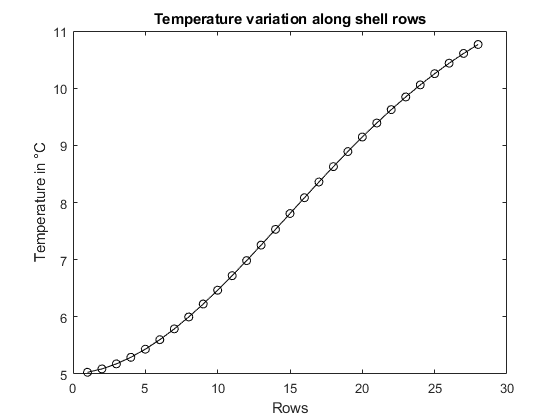

x = linspace(1,N_r,N_r);
figure();
plot(x,To,'-ok');
xlabel('Rows');
ylabel('Temperature in °C');
title('Temperature variation along shell rows');

## 14. Cost Estimation

The 2010 model is used for estimating total costs. The coefficients are taken from the table in Sinnott and Towler. We get the following:

a = 28000; b = 54; n = 1.2;
S = A0/N_hex;

The total cost per heat exchanger is proportional to the heat transfer area, and hence, a simple power law is employed.

C = a + b * S^n; % in USD
C_T = C*N_hex;
C_T = C_T*0.92; % in EUR

The obtained cost is multiplied by the inflation factor of 1.14 to obtain the cost of equipment in euros in 2020 as

Cost_equipment = C_T * 1.14 % in EUR

Cost_equipment = 2.6925e+06

The total capital costs associated with the heat exchanger includes the installation and maintenance costs which have a multiplying factor of 3.5. Hence, the total cost is

Cost_total = Cost_equipment*3.5 % in EUR

Cost_total = 9.4238e+06

The above costs are nominal considering the heat exchangers are industrial grade and heavy duty.